# IV curve under light SuSi Bouzidi

Solar cell parameters estimation through algorithm by Bouzidi et al.,

2007, doi:10.1016/j.solmat.2007.05.019.

clearvars
close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'))

TEMPERATURE = 298; % 25°C in K
V_T = 0.02585*TEMPERATURE/300; % Thermal voltage in V

% n = 2.18;

% Import
LPath = 'd:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.txt';
dummyStr = strsplit(LPath, '.');
SPath = [dummyStr{1}, '.mat'];
clear dummyStr

if endsWith(LPath, '.lvm')
    % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);
elseif endsWith(LPath, '.txt')
    % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    V = ivdata.data(:,1);
    I = ivdata.data(:,2)*1e-3;
end

Index in position 2 exceeds array bounds. Index must not
exceed 1.


[V, I] = checksigns(V, I);

I = I + 1e-3;
% Plot
figure()
plot(V, I, 'o')
xlim([min(V) max(V)])
grid()

## Linear fit on reverse bias region

Define region

VRange = [-1 0.4];
idx = (V > VRange(1)) & (V < VRange(2));
V_ = V(idx);
I_ = I(idx);

% Fit with esfit
linModel = @(p, V) p(1)*V + p(2);
p0 = [-1e-6, 1e-7]; pVary = [1, 1];
esfitOpt.PrintLevel = 0; % Still not working in 6.0.0-dev.45
fitRev = esfit(I_, @(p)linModel(p, V_), p0, pVary, esfitOpt);

-- esfit ------------------------------------------------
Data size:                [2, 1]
Model function name:      @(p)linModel(p,V_)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.14187e-09   edge 1.00000e-01   initial simplex
iteration   2: value 1.14187e-09   edge 2.00000e-01   reflection
iteration   3: value 1.14187e-09   edge 2.00000e-01   reflection
iteration   4: value 5.70937e-10   edge 2.00000e-01   reflection
iteration   5: value 5.70937e-10   edge 2.00000e-01   contraction inside
iteration   6: value 5.70937e-10   edge 2.00000e-01   contraction inside
iteration   7: value 5.70937e-10   edge 2.00000e-01   contraction inside
iteration   8: value 5.70937e-10   edge 2.00000e-01   contraction inside
iteration   9: value 5.70937e-10   edge 2.00000e-0

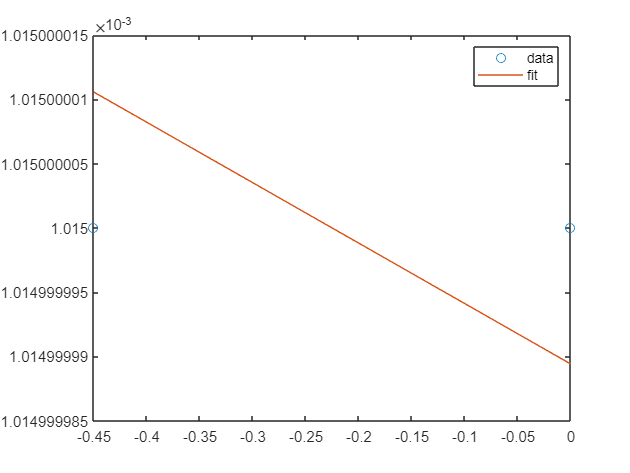

fitRev.pnames = {'-Ga', 'Ipa'};
scale = fitRev.scale; % Short name
Ga = -fitRev.pfit(1)*scale; Ipa = fitRev.pfit(2)*scale;
dGa = fitRev.pstd(1)*scale; dIpa = fitRev.pstd(2)*scale;

% Check fit
checklinfit(V_, I_, fitRev);

% Save into structure
Iv.fitRev = struct('V', V_, ...
    'I', I_, ...
    'model', linModel, ...
    'p0', p0, ...
    'pVary', pVary, ...
    'fit', fitRev);

% Plot
xDummy = min(V_):0.01:max(V_);
figure()
plot(V_, I_, 'o'); hold on; plot(xDummy, linModel([-Ga, Ipa], xDummy))
xlim([min(V_) max(V_)])
legend('data', 'fit')

## Nonlinear fit on forward bias region

Ic = I + Ga*V; % Corrected current

% Define region
VRange = [0.5 1.5];
idx = (V > VRange(1)) & (V < VRange(2));
V_ = V(idx);
I_ = I(idx);
Ic_ = Ic(idx);

% Fit with esfit
nonLinModel = @(C, I, Ic) C(1) + C(2)*I + C(3)*log(1 - Ic/Ipa);
p0 = [V_T, -1, V_T]; % Initial values for [n*ln(Ipa/I0)*V_T, -Rs, n*V_T]
pVary = [10, 1e6, 10];

fitForw = esfit(V_, @(p)nonLinModel(p, I_, Ic_), p0, pVary, esfitOpt);
fitForw.pnames = {'n*ln(Ipa/I0)*V_T', '-Rs', 'n*V_T'};

checknonlinfit(V_, I_, Ic_, p0, nonLinModel, fitForw)

% Save into structure
Iv.fitForw = struct('V', V_, ...
    'I', I_, ...
    'Ic', Ic_, ...
    'model', nonLinModel, ...
    'p0', p0, ...
    'pVary', pVary, ...
    'fit', fitForw);

% Plot
figure()
plot(I_, V_, I_, nonLinModel(fitForw.pfit*fitForw.scale, I_, Ic_))
legend('data', 'fit')

scale = fitForw.scale; % Short name
Rs = -fitForw.pfit(2)*scale;
dRs = fitForw.pstd(2)*scale;
n = fitForw.pfit(3)*scale/V_T;
dn = fitForw.pstd(3)*scale/V_T;
% V_T = fitForw.pfit(3)*scale/n;
% dV_T = fitForw.pstd(3)*scale/n;
I0 = Ipa*exp(-fitForw.pfit(1)/fitForw.pfit(3)); % scale gets simplificated here
dI0 = I0*sqrt( (1/Ipa*dIpa)^2 ...
    + (1/fitForw.pfit(2)*fitForw.pstd(1)*scale)^2 ...
    + (fitForw.pfit(1)/(fitForw.pfit(3)^2)*fitForw.pstd(2)*scale)^2 ...
    );
Is = I0/(1 - Ga*Rs);
dIs = sqrt( (1/(1-Ga*Rs)*dI0)^2 ...
    + (Is*Rs/(1 - Ga*Rs)*dGa)^2 ...
    + (Is*Ga/(1 - Ga*Rs)*dRs)^2 ...
    );
Gsh = Ga/(1 - Ga*Rs);
dGsh = sqrt( (1/(1 - Ga*Rs)*dGa)^2 ...
    + (Gsh*Rs/(1 - Ga*Rs)*dGa)^2 ...
    + (Gsh*Ga/(1 - Ga*Rs)*dRs)^2 ...
    );
Rpar = 1/Gsh;
dRpar = Rpar/Gsh*dGsh;
Iph = Ipa/(1 - Ga*Rs);
dIph = sqrt( (1/(1 - Ga*Rs)*dI0)^2 ...
    + (Iph*Rs/(1 - Ga*Rs)*dGa)^2 ...
    + (Iph*Ga/(1 - Ga*Rs)*dRs)^2 ...
    );

% Save into struct
Iv.cellParam = [Rs; Rpar; Is; Iph; n];
Iv.cellParamStd = [dRs; dRpar; dIs; dIph; dn];
Iv.cellParamNames = {'Rs'; 'Rpar'; 'Is'; 'Iph'; 'n'};
save(SPath, '-struct', 'Iv')

Ifinal = Iph - Is*(exp((V + Rs*I)/n/V_T) - 1) - (V + Rs*I)/Rpar;
figure()
plot(V, I, V, Ifinal)

function [V, I] = checksigns(V, I)
% Return I in such a way that Iph is positive. This is equivalent to have 
% the forward bias regime in the forth (lower right) quadrant.
% The function works for IV curves with forward bias on the first 
% (upper right) quadrant and third (lower left) quadrant.
% Return V in ascending order.
%
% [V, I] = checksigns(V, I)
% Input:
%   V   voltage, vector of length n
%   I   current, vector of length n
%
% Output:
%   V   voltage in ascending order
%   I   current with forward bias region in the forth quadrant

[~, idx] = max(abs(I));
if idx < 10
    % IV curve in the third quadrant
    V = -V;
else
    % IV curve in the first quadrant
    I = -I;
end

% Return V in ascending order
if V(end) < V(1)
    V = flip(V);
    I = flip(I);
end
end

function [] = checklinfit(V_, I_, fit)
% Displays a warning if the best fit parameters from esfit and from linear
% regression of the type y = m*x + q aren't equal (up to roughly the 
% fourth significative digit)
%
% [] = checklinfit(V_, I_, fit)
% Input:
%   V_      voltage, vector of length n
%   I_      current, vector of length n
%   fit     structure with fitting results, output of esfit

% Check if fit is a structure obtained as output from esfit
if ~isfield(fit, {'pfit' 'scale'})
    warning('checkLinFit error: the parameter "fit" does not have pfit and scale fields')
    return
end

% Linear regression
X = [V_, ones(numel(V_), 1)];
param = X\I_; param = param(1:numel(fit.pfit));

% Check (up to roughly fourth significative digit)
if abs(param - fit.pfit*fit.scale) > 1e-4*param
    warning('Linear regression and esfit return different values for bestfit parameters')
end
end

function [] = checknonlinfit(V_, I_, Ic_, p0, model, fit)
% Displays a warning if the best fit parameters from esfit and from 
% least-square non linear fitting are equal (up to roughly the 
% fourth significative digit)
%
% [] = checknonlinfit(V_, I_, Ic_, p0, model, fit)
% Input:
%   V_      voltage, vector of length n
%   I_      current, vector of length n
%   Ic_     corrected current, Ic_ = I_ + Ga*V_
%   p0      vector with initial values for the
%           least-square non linear fit
%   model   model used in the least-square non linear fit
%   fit     structure with fitting results, output of esfit

% Check if fit is a structure obtained as output from esfit
if ~isfield(fit, {'pfit' 'scale'})
    warning('checkNonLinFit error: the parameter "fit" does not have pfit and scale fields')
    return
end

% Least-square non linear fit
param = lsqnonlin(@(C) (V_ - model(C, I_, Ic_)), p0);

% Check (up to roughly fourth significative digit)
if abs(param - fit.pfit*fit.scale) > 1e-4*param
    warning('Linear regression and esfit return different values for bestfit parameters')
end
end